xycsvファイルの内容を確認

readtable("001-7mm.csv")

ans = 25604×32 table
    exx    eyy        exy            e1            e2          gamma     fxx        fxy            fyx            fyy        sigma    l_x    l_y    F_XX    F_YY       F_XY           F_YX        F_ZZ    B_YY       B_XY        B_XX       B_YX        B_ZZ    I_1    I_2    myu     x     y     u    v    Xp    Yp
    ___    ___    ___________    __________    ___________    _______    ___    ___________    ___________    ___________    _____    ___    ___    ____    ____    ___________    ___________    ____    ____    ___________    ____    ___________    ____    ___    ___    ___    ___    __    _    _    __    __

     0      0     -1.0952e-16     5.476e-17     -5.476e-17    -0.7854     0     -5.8159e-17    -5.1361e-17    -4.9576e-17      1       1      1      1       1      -5.8159e-17    -5.1361e-17     1       1      -1.0952e-16     1      -1.0952e-16     1       3      3     -1       9    87    0    0    0     0 
     0      0     -9.8333e-17    4.9167e-17    -4.9

readtable("011-12.6mm.csv")

ans = 25604×32 table
    exx    eyy    exy    e1    e2    gamma    fxx    fxy    fyx    fyy    sigma    l_x    l_y    F_XX    F_YY    F_XY    F_YX    F_ZZ    B_YY    B_XY    B_XX    B_YX    B_ZZ    I_1    I_2    myu     x     y       u          v       Xp    Yp
    ___    ___    ___    __    __    _____    ___    ___    ___    ___    _____    ___    ___    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ___    ___    ___    ___    __    ______    _______    __    __

     0      0      0     0     0       0       0      0      0      0      -1       0      0      0       0       0       0       0       0       0       0       0       0       0      0      0       9    87    44.407    -101.26    0     0 
     0      0      0     0     0       0       0      0      0      0      -1       0      0      0       0       0       0       0       0       0       0       0       0       0      0      0      17    87    44.488       -101    0     0 
     0      0 

csvファイルの読み込み

% CSVファイルの読み込み
data = readmatrix('001-7mm.csv')

data = 1.0e+03 *

         0         0   -0.0000    0.0000   -0.0000   -0.0008         0   -0.0000   -0.0000   -0.0000    0.0010    0.0010    0.0010    0.0010    0.0010   -0.0000   -0.0000    0.0010    0.0010   -0.0000    0.0010   -0.0000    0.0010    0.0030    0.0030   -0.0010    0.0090    0.0870         0         0         0         0
         0         0   -0.0000    0.0000   -0.0000   -0.0008         0   -0.0000   -0.0000   -0.0000    0.0010    0.0010    0.0010    0.0010    0.0010   -0.0000   -0.0000    0.0010    0.0010   -0.0000    0.0010   -0.0000    0.0010    0.0030    0.0030   -0.0010    0.0170    0.0870         0         0         0         0
         0         0   -0.0000    0.0000   -0.0000   -0.0008         0   -0.0000   -0.0000   -0.0000    0.0010    0.0010    0.0010    0.0010    0.0010   -0.0000   -0.0000    0.0010    0.0010   -0.0000    0.0010   -0.0000    0.0010    0.0030    0.0030   -0.0010    0.0250    0.0870         0         0         0         0
         0         


% x座標、y座標、および数値データの取得
x_coordinates = data(:, 27); % 27列目のデータをx座標として取得
y_coordinates = data(:, 28); % 28列目のデータをy座標として取得
pixel_values = data(:, 4);   % 4列目のデータを画素値として取得



カラーバーを用いた可視化

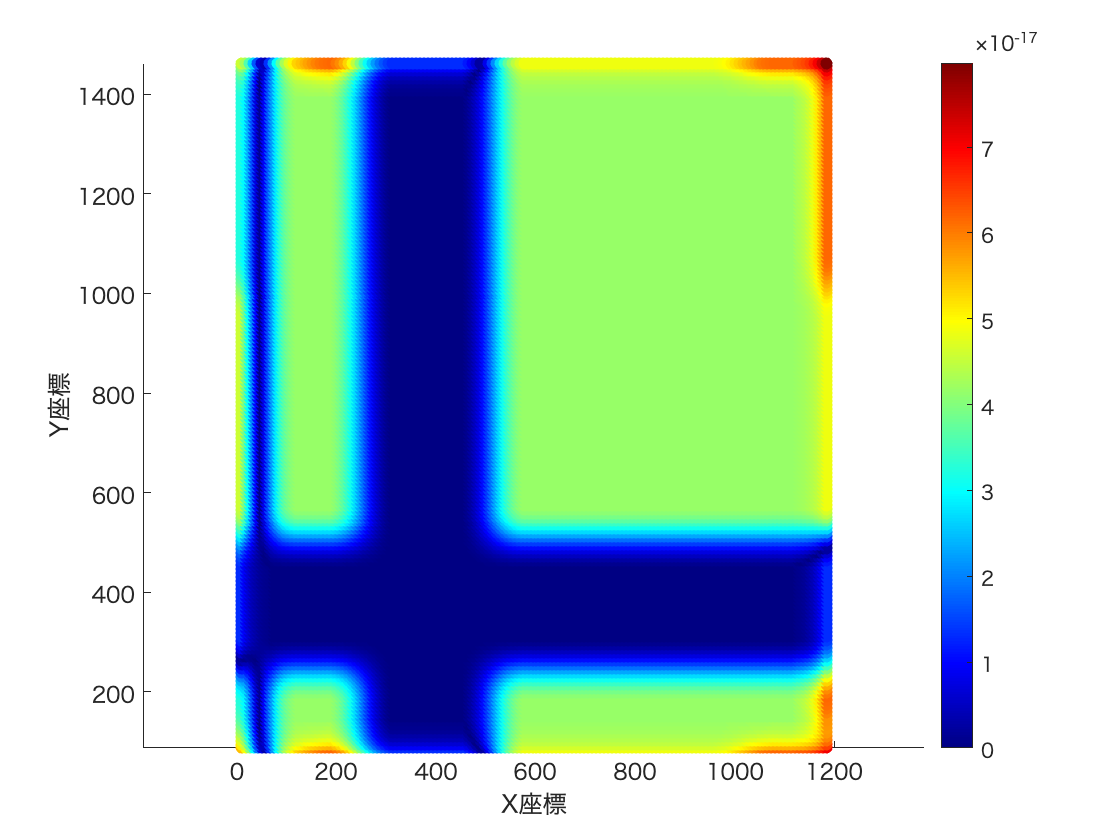

% カラーマップを選択
colormap('jet');

% 散布図をプロットし、カラーバーを表示
scatter(x_coordinates, y_coordinates, [], pixel_values, 'filled');
colorbar;

% 軸のラベルを設定（必要に応じて）
xlabel('X座標');
ylabel('Y座標');

% 縦横比を1:1に設定
axis equal;

% CSVファイルが格納されたディレクトリのパスを指定
csv_directory = 'csvPath';

% ディレクトリ内のCSVファイルをリストアップ
csv_files = dir(fullfile(csv_directory, '*.csv'))

csv_files = フィールドをもつ 11×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


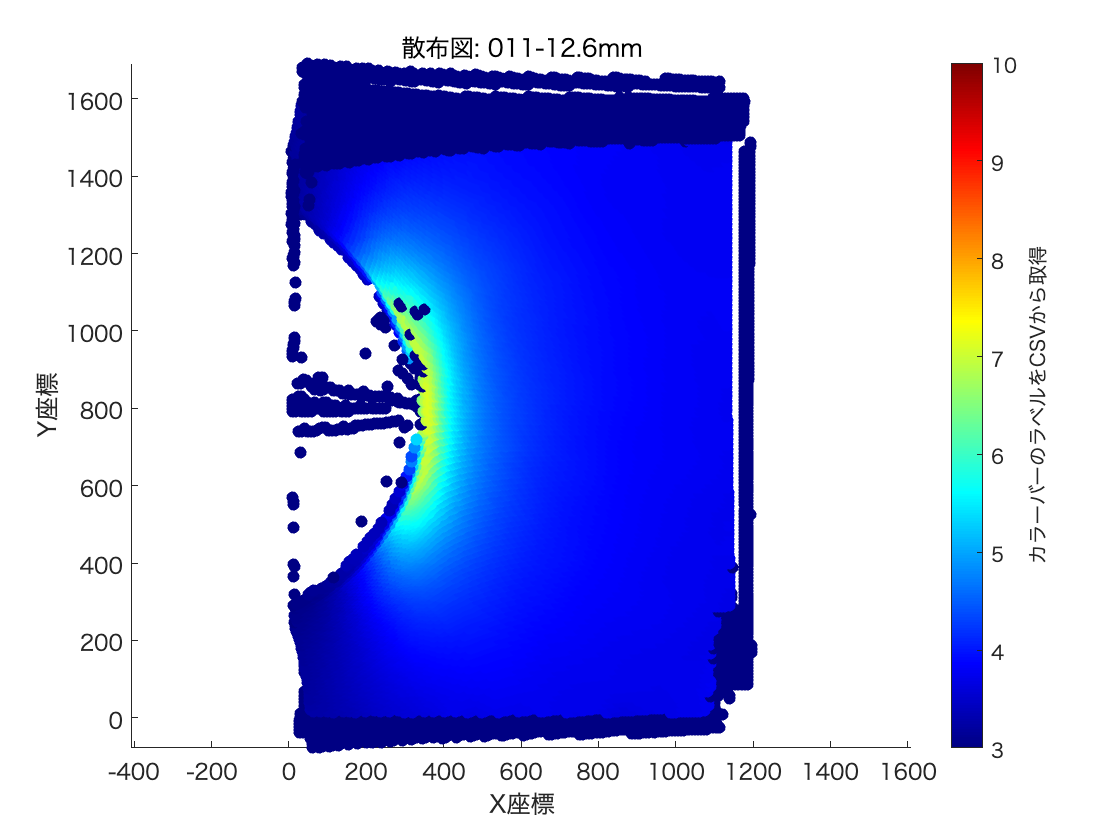


% カラーマップを選択
colormap('jet');

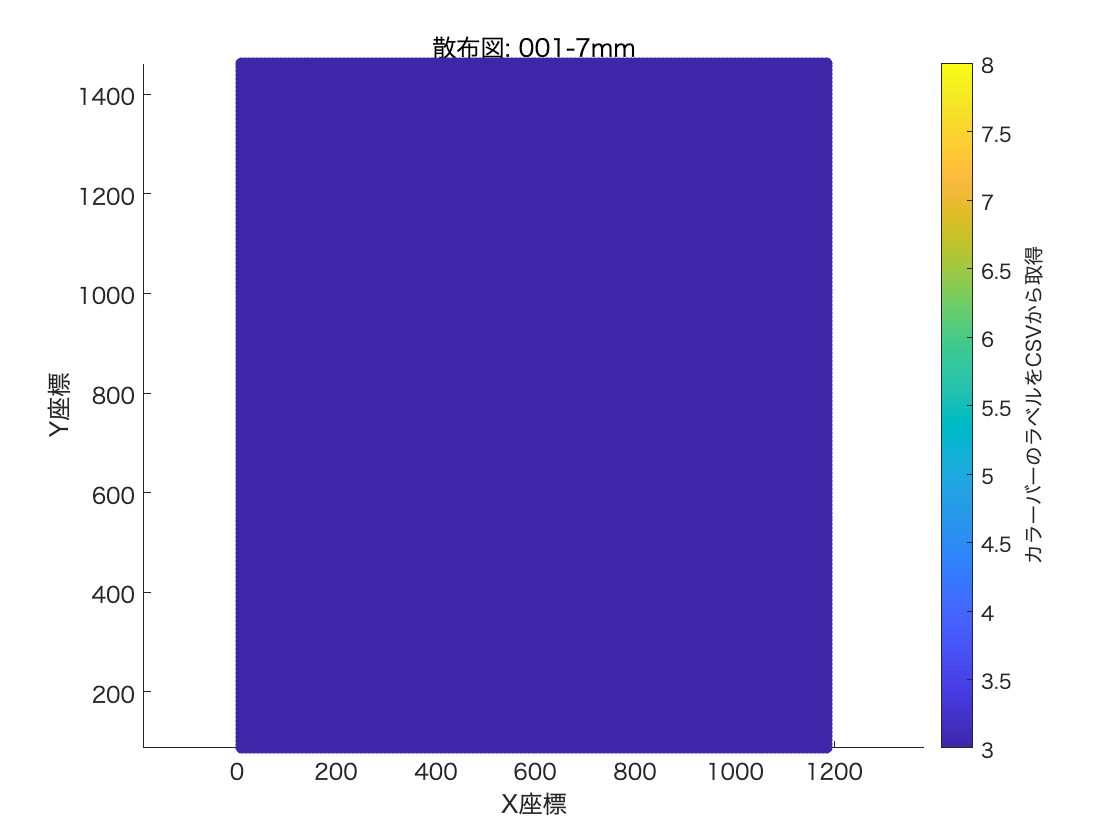

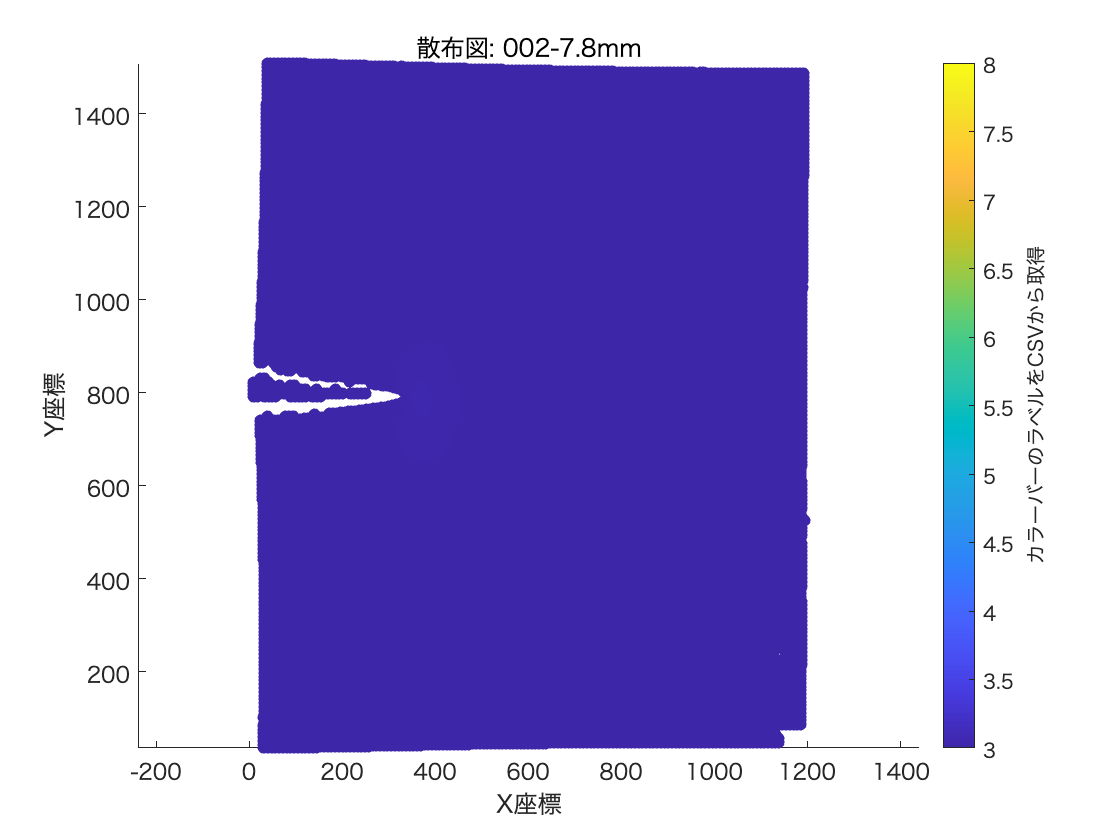

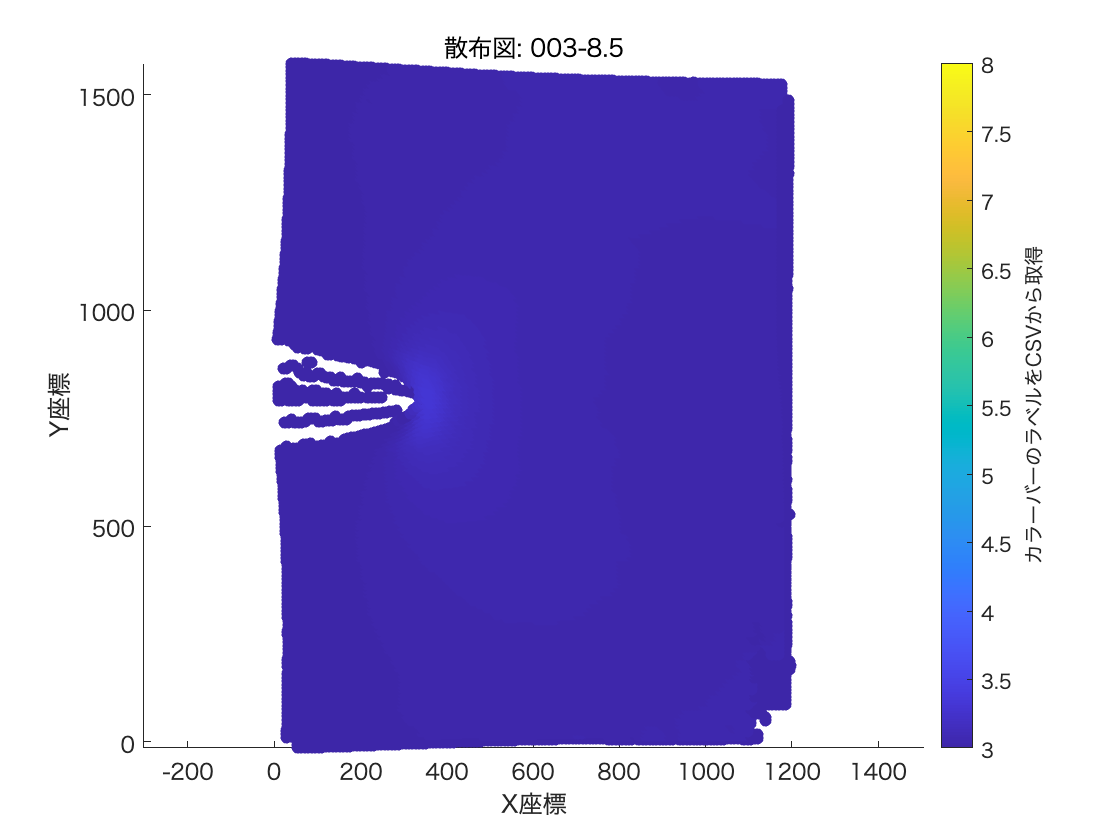

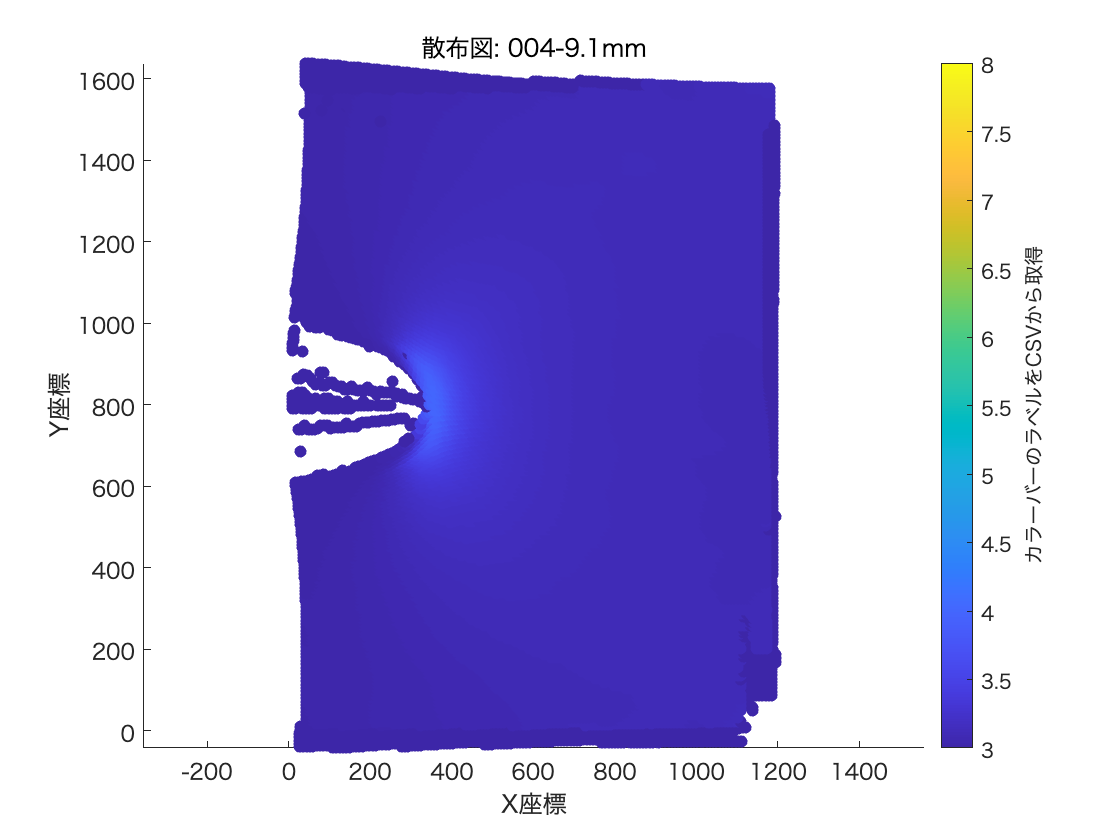

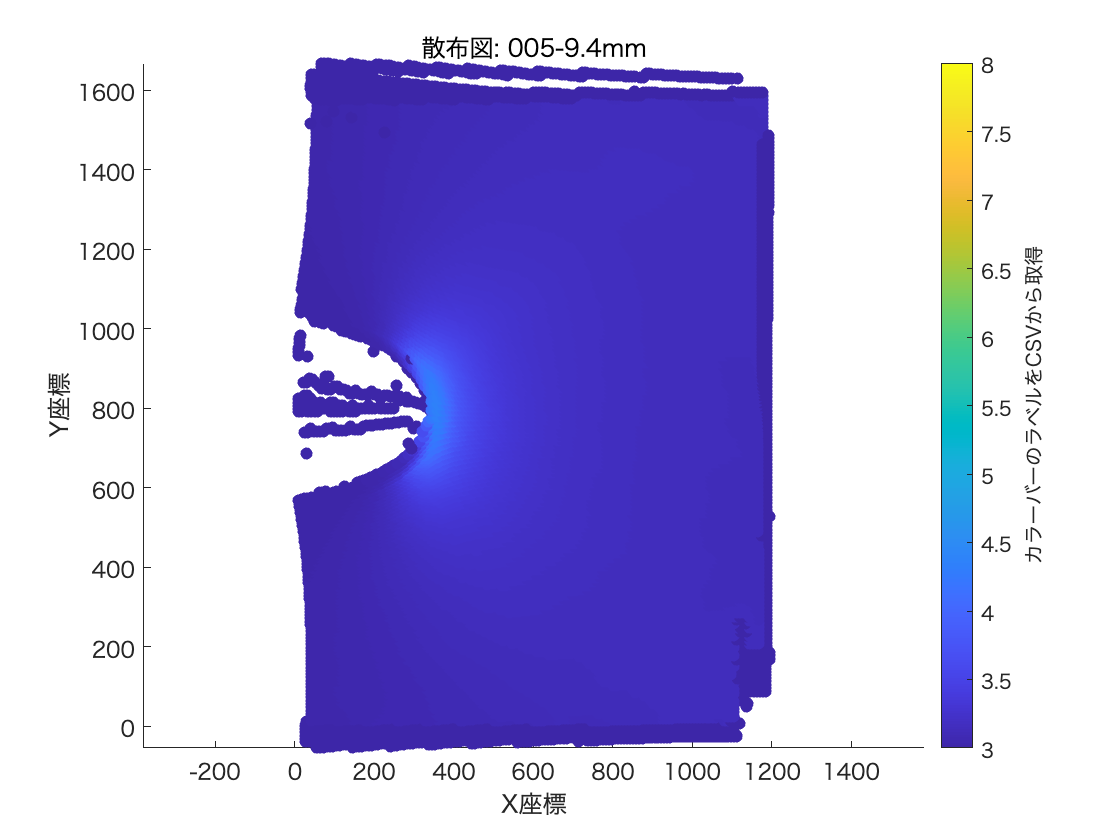

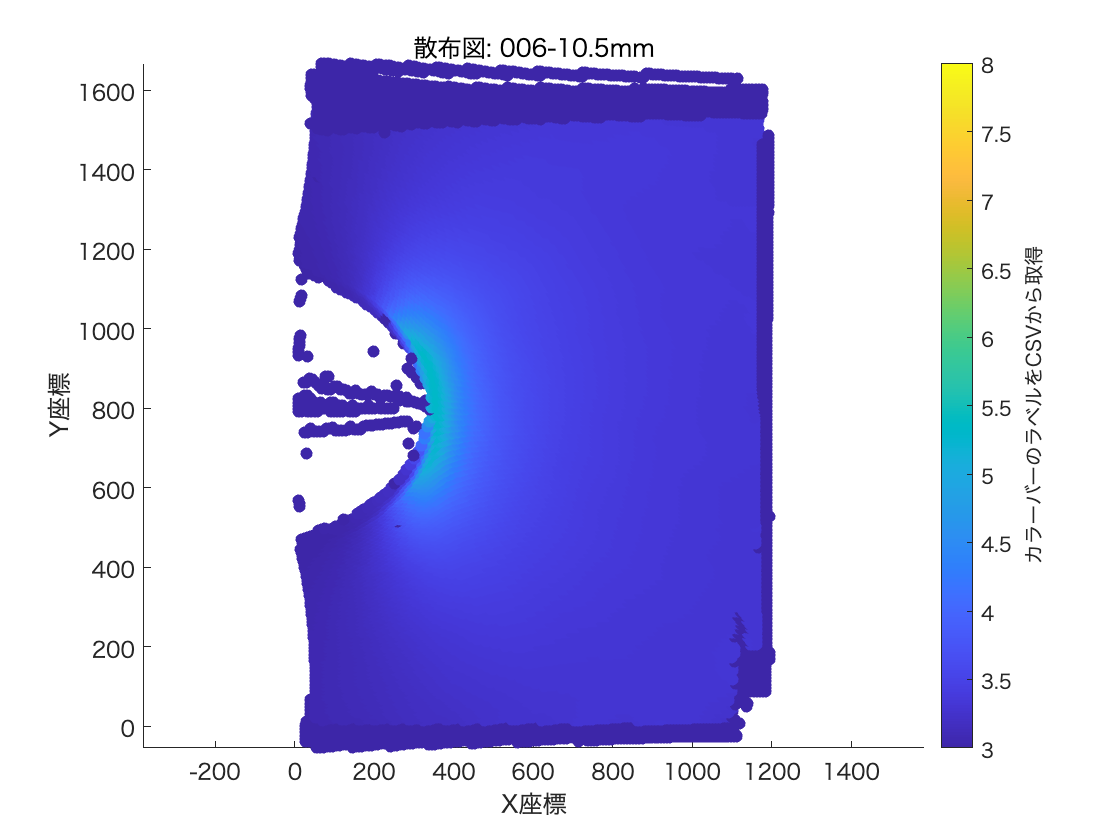

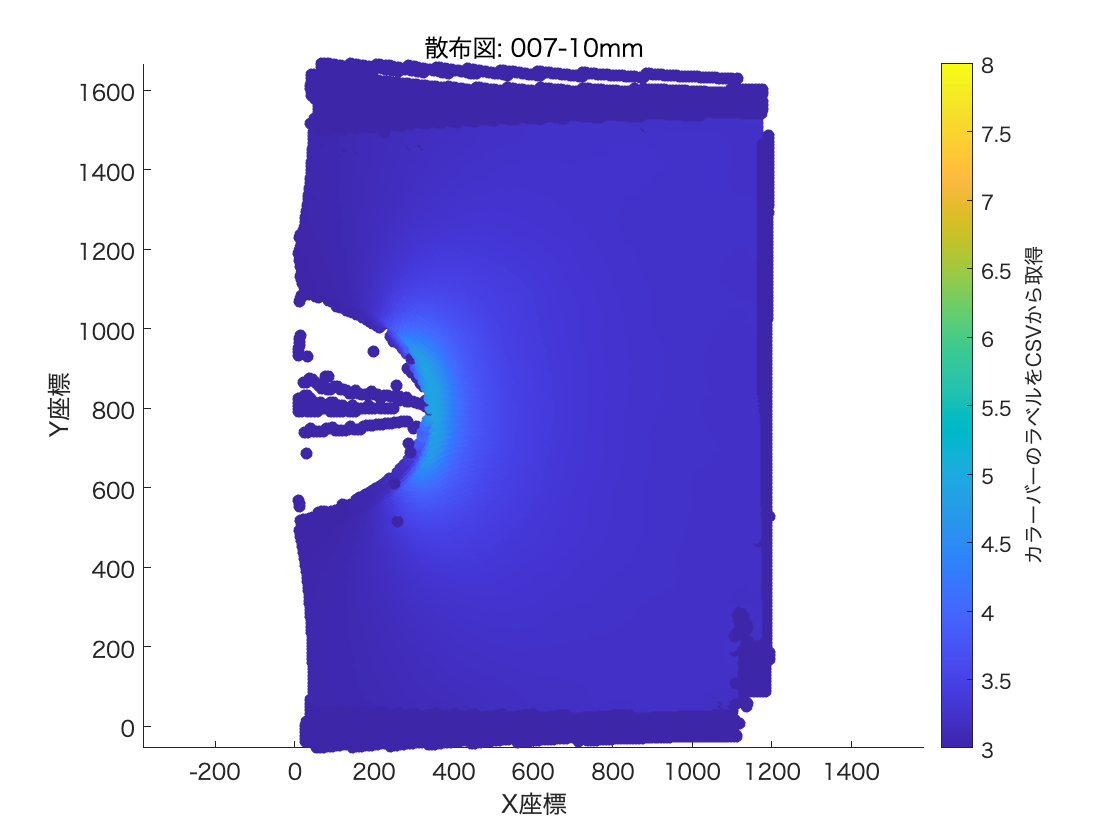

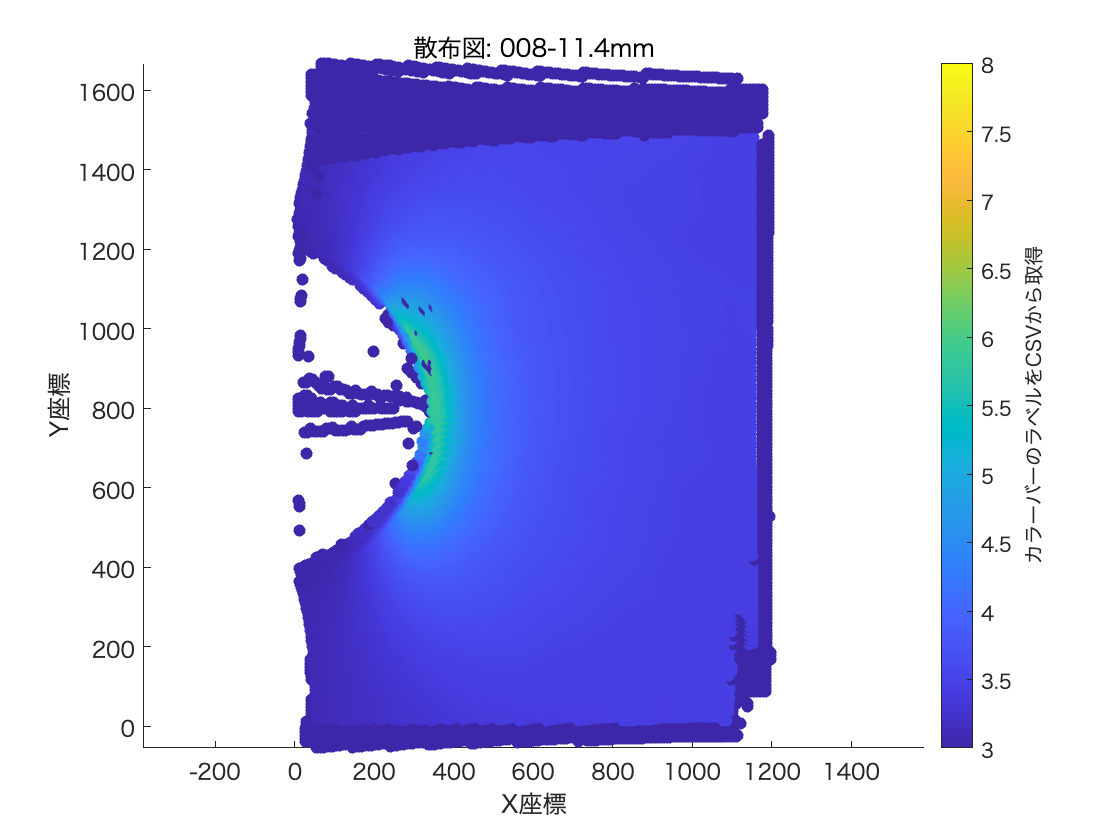

% 各CSVファイルに対して処理を繰り返す
for i = 1:numel(csv_files)
    % CSVファイルの読み込み（readtableを使用）
    csv_data = readtable(fullfile(csv_directory, csv_files(i).name));
    
    % x座標、y座標、および数値データの取得
    x_coordinates = csv_data.x + csv_data.u; % x座標の列名を適宜変更
    y_coordinates = csv_data.y + csv_data.v; % y座標の列名を適宜変更
    pixel_values = csv_data.I_1; % 数値データの列名を適宜変更
    
    % 新しい図を作成
    figure;
    
    % 散布図をプロットし、カラーバーを表示
    scatter(x_coordinates, y_coordinates, [], pixel_values, 'filled');
    h = colorbar; % カラーバーオブジェクトを取得
    
    % カラーバーの最小値を3に設定
    caxis([3, 8]);
   
    % 軸のラベルを設定（必要に応じて）
    xlabel('X座標');
    ylabel('Y座標');
    
    % 縦横比を1:1に設定
    axis equal;
    
    % グラフのタイトルを設定（ファイル名から取得）
    [~, file_name, ~] = fileparts(csv_files(i).name);
    title(['散布図: ', file_name]);
    
    % カラーバーのラベルを設定（CSVファイルから取得）
    colorbar_label = ''; % CSVファイルからラベルを取得
    ylabel(h, colorbar_label);
    
    % 保存などの追加の処理を行うことも可能
    
    % フィギュアを保存（任意）
    %saveas(gcf, ['scatter_', file_name, '.png']);
    
    % クローズして次のファイルに進む
    %close(gcf);
end

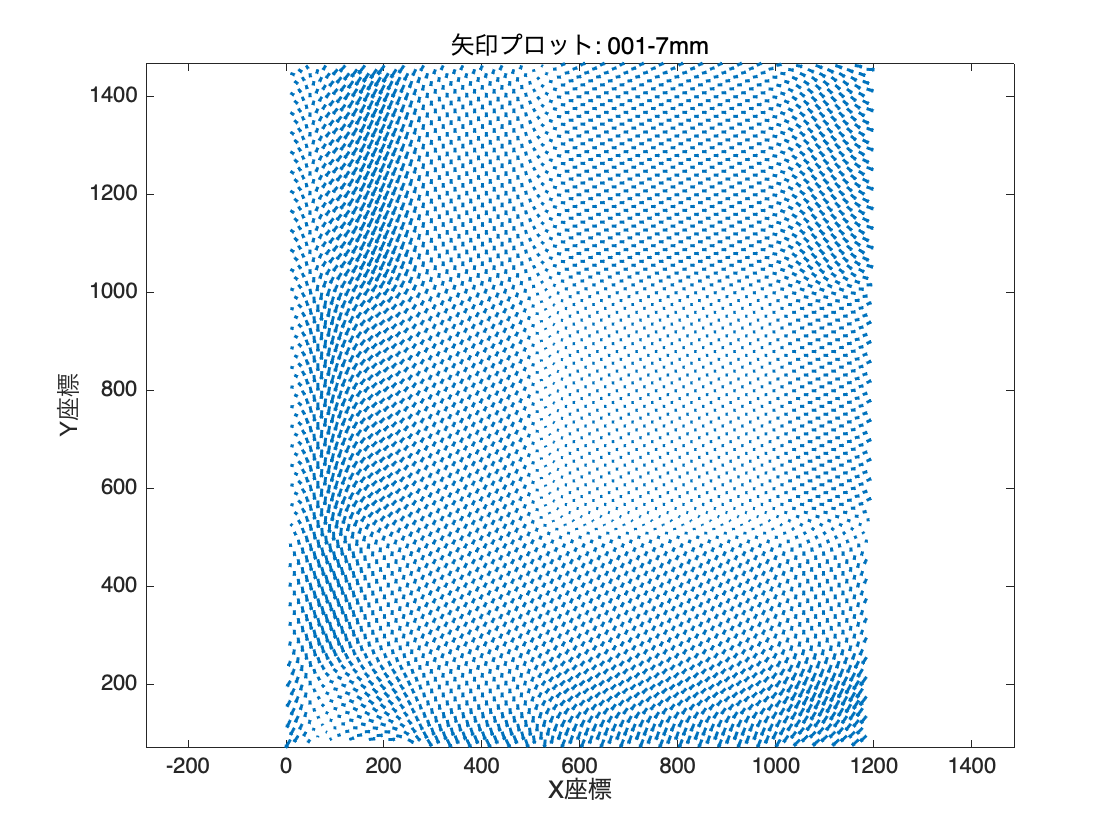

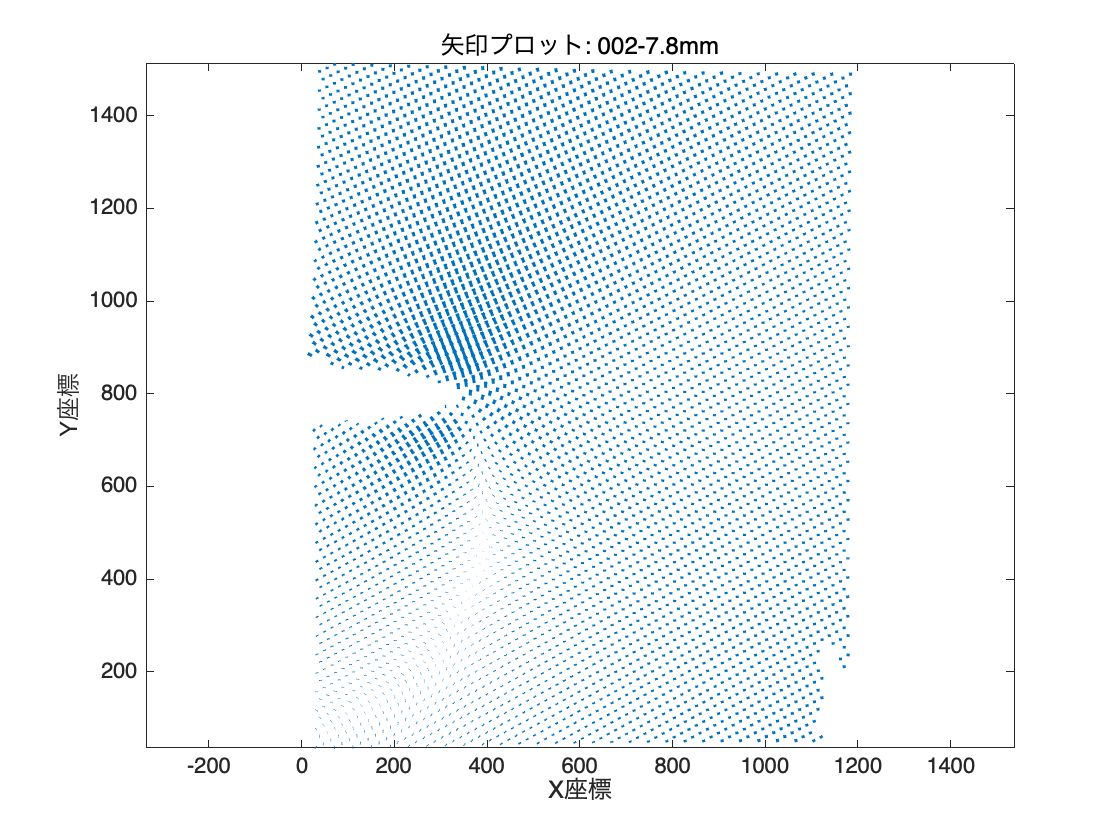

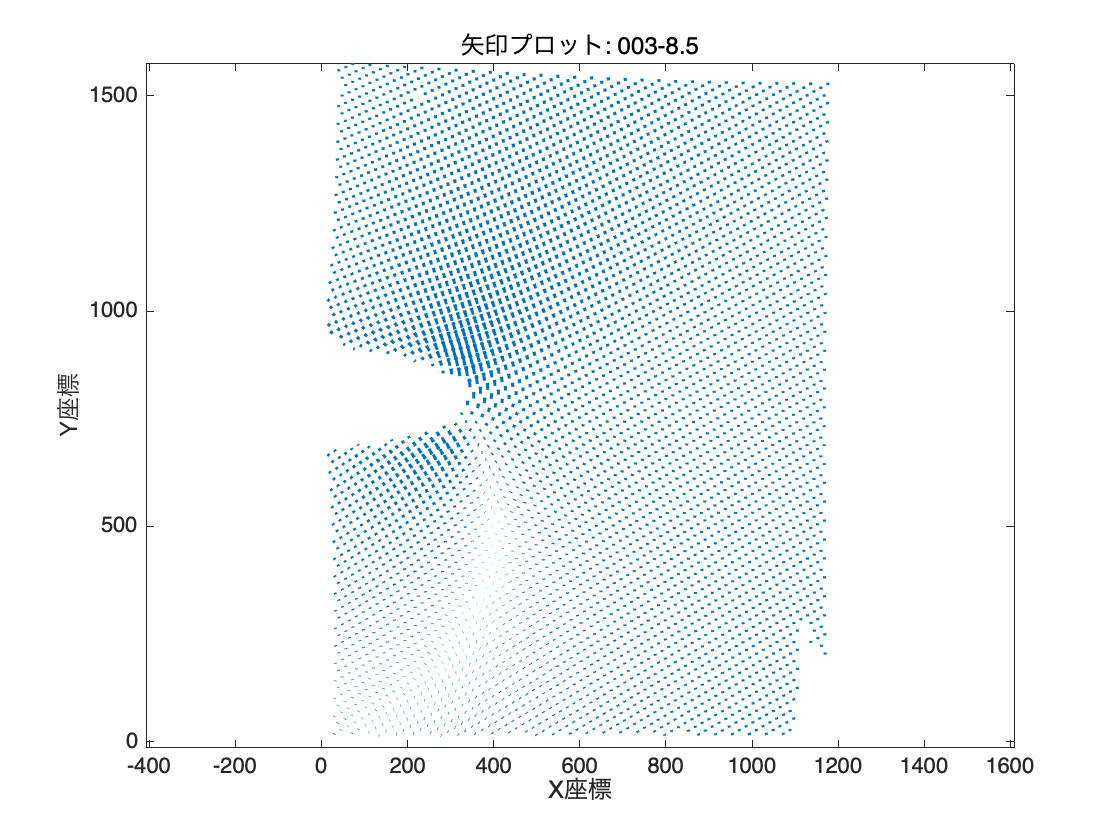

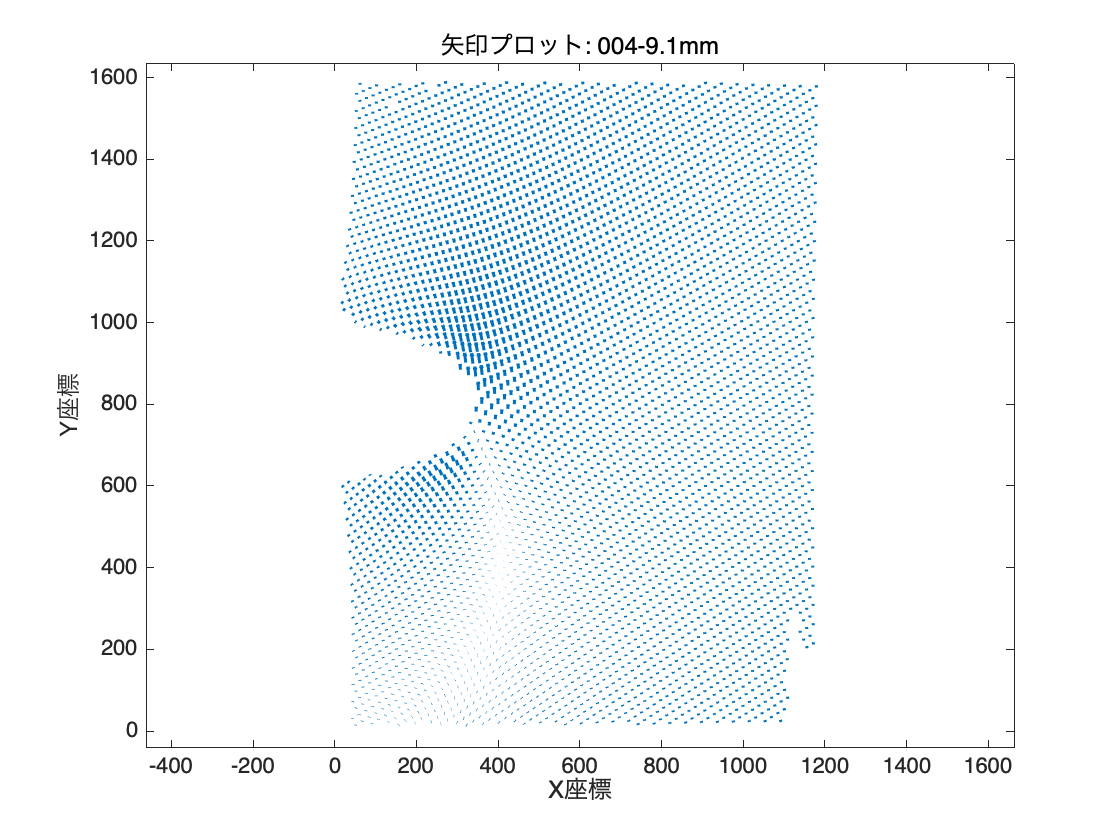

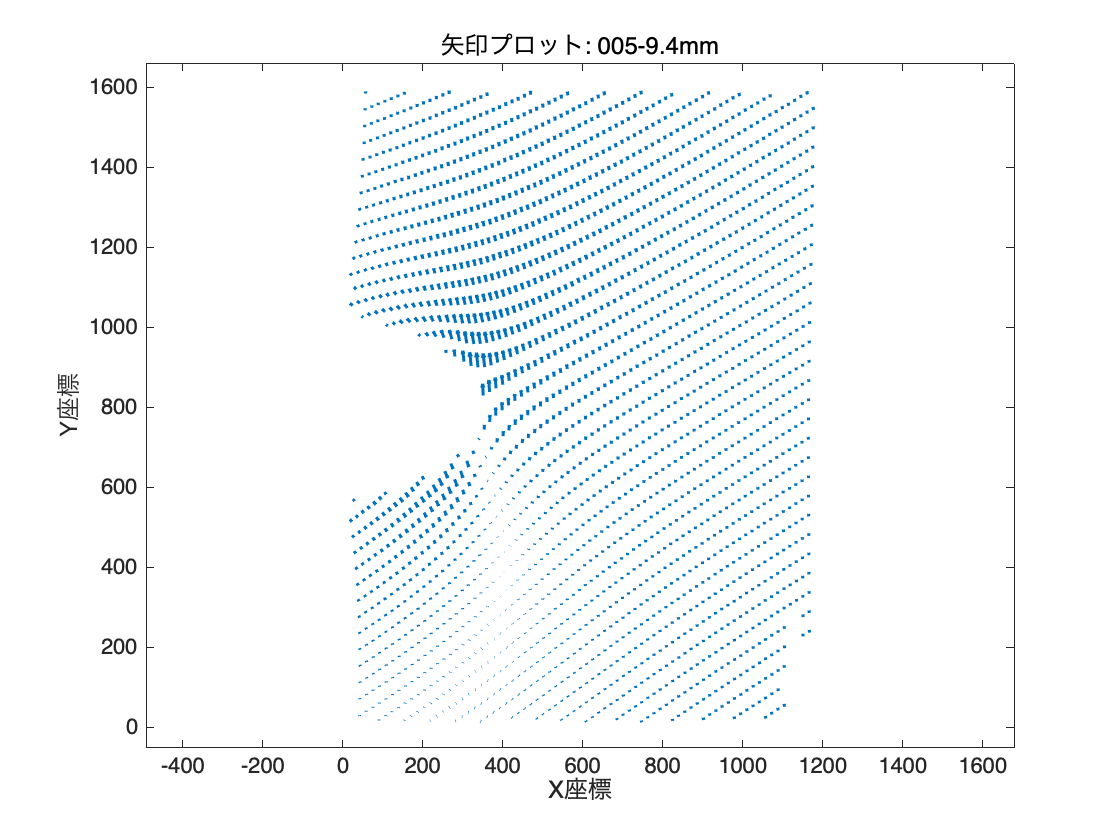

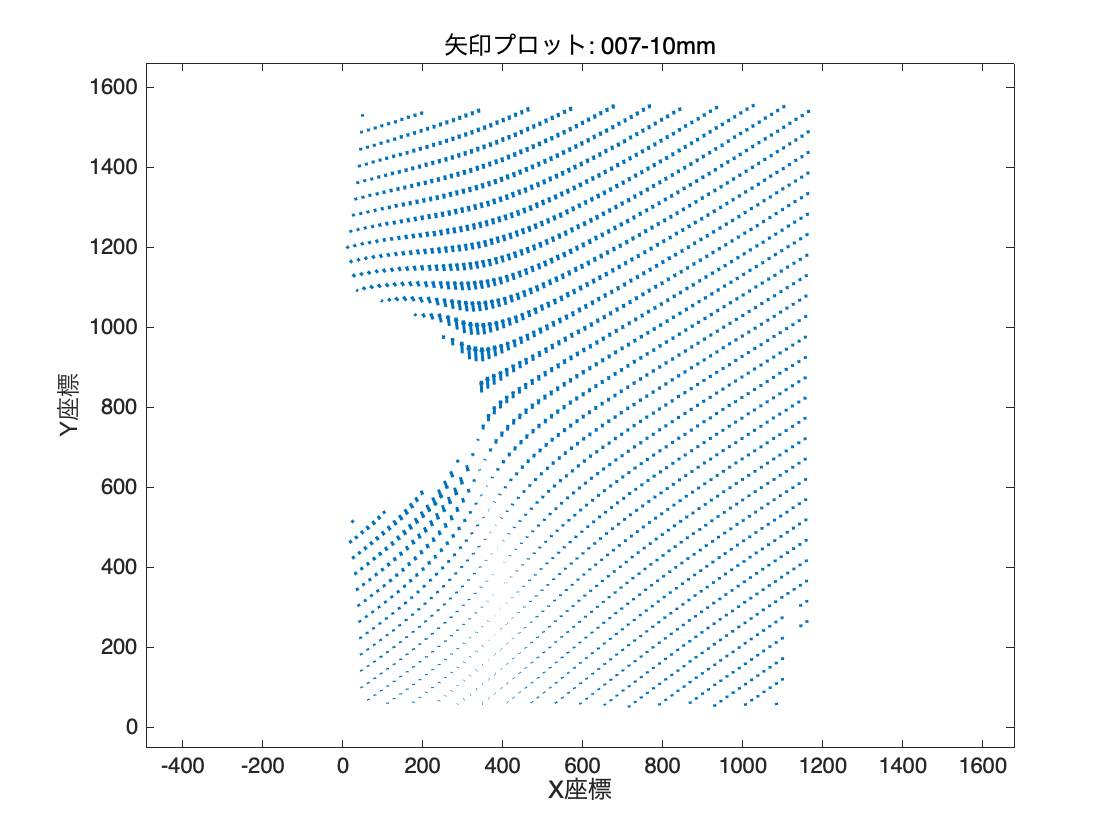

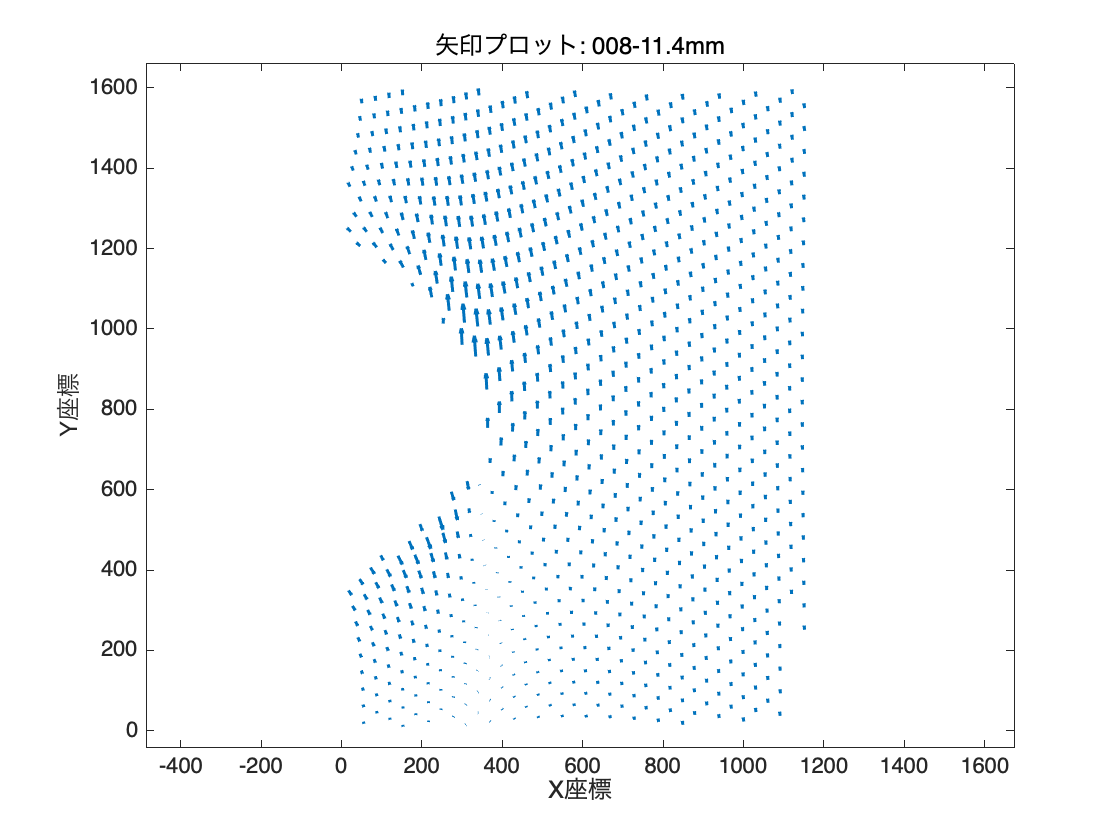

% 各CSVファイルに対して処理を繰り返す
for i = 1:numel(csv_files)
    % CSVファイルの読み込み（readtableを使用）
    csv_data = readtable(fullfile(csv_directory, csv_files(i).name));
    
    % x座標、y座標、および2つのxy方向の数値の取得
    x_coordinates = csv_data.x + csv_data.u; % x座標の列名を適宜変更
    y_coordinates = csv_data.y + csv_data.v; % y座標の列名を適宜変更
    u_values = csv_data.fxx + csv_data.fxy;     % x方向の数値の列名を適宜変更
    v_values = csv_data.fyy + csv_data.fyx;     % y方向の数値の列名を適宜変更
    
    % 飛ばし飛ばしに表示するインデックスを選択
    skip = 5; % 4つおきに矢印を表示する場合（必要に応じて変更）
    selected_indices = 1:skip:numel(x_coordinates);
    
    % 新しい図を作成
    figure;
    
    % quiver関数に選択された座標を渡して矢印をプロット
    quiver(x_coordinates(selected_indices), y_coordinates(selected_indices), ...
           u_values(selected_indices), v_values(selected_indices), 'LineWidth', 1.5);
    
    % 軸のラベルを設定（必要に応じて）
    xlabel('X座標');
    ylabel('Y座標');
    
    % 縦横比を1:1に設定
    axis equal;
    
    % グラフのタイトルを設定（ファイル名から取得）
    [~, file_name, ~] = fileparts(csv_files(i).name);
    title(['矢印プロット: ', file_name]);
    
    % 保存などの追加の処理を行うことも可能
    
    % フィギュアを保存（任意）
    %saveas(gcf, ['arrow_plot_', file_name, '.png']);
    
    % クローズして次のファイルに進む
    %close(gcf);
end